This File will plot the metrics HammingDistance and SuccesProbability

For different Defective amounts

CASES = 100; % amount of elements sparse vector
AmountOfSamples = 500;
NoiseParameter = 0.00; % will be zero



% These parameters can be changed to make the code run faster
krange = 1:1:15; 
iterations =300; 

% Initializing plot arrays. If no name is given it is DD algorithm
xMeasurment = zeros(length(krange),1);
yplot = zeros(length(krange),1);
yplot_lin_prog  = yplot;


yplot_COMP  = yplot;
yplot_SCOMP  = yplot;


%Succes prob
ySplot = yplot;
ySplot_lin_prog  = yplot;
ySplot_COMP  = yplot;
ySplot_SCOMP  = yplot;

% formula for Bernouli design
p = (1/(k+1));


plotindex = 1;

%Outerloop will run for each k, innerloop will do it multiple times
% to achieve a good average performance       
for k = krange
    M = 85;

    %Sparse matrix created for given k.
    x = MakeSparseMatrix(CASES,iterations,k); 

    A_example = generateA(p, M, CASES);
    disp(k)
    sum = 0;
    sum_lin_prog = 0;
    sum_COMP = 0;
    sum_SCOMP = 0;


    sumS = 0;
    sumS_lin_prog = 0;
    sumS_COMP = 0;
    sumS_SCOMP = 0;
    for i = 1:iterations
        x_groundTruth = x(:,i);%take a sample
        
        
        Noise = rand(M, 1) < NoiseParameter;
        

        y = double(xor(sign(A_example*x_groundTruth),double(Noise)));
        
        [x_output] = calcDD(A_example,y, CASES); %DD
        [hamming_distance] = calcHammingDist(x_groundTruth, x_output');
        [resultSucess] = IsSuccesfull(x_groundTruth, x_output');
        
        [x_output_linear_prog,Z] = LPrelax(A_example,y); % LPrelaxAlgoritm
        [hamming_dstance_linear_prog] = calcHammingDist(x_groundTruth, x_output_linear_prog);
        [resultSucess_linear_prog] = IsSuccesfull(x_groundTruth, x_output_linear_prog);

        [x_output_COMP] = calcCOMP(A_example,y,CASES); % COMP
        [hamming_dstance_COMP] = calcHammingDist(x_groundTruth, x_output_COMP');
        [resultSucess_COMP] = IsSuccesfull(x_groundTruth, x_output_COMP');


        [x_output_SCOMP] = calcSeqCOMP(A_example, y, CASES); % COMP
        [hamming_dstance_SCOMP] = calcHammingDist(x_groundTruth, x_output_SCOMP');
        [resultSucess_SCOMP] = IsSuccesfull(x_groundTruth, x_output_SCOMP');
        
        %Summing performance metrics to calculate averages.
        sum = sum + hamming_distance;
        sum_lin_prog = sum_lin_prog + hamming_dstance_linear_prog;
        sum_COMP = sum_COMP + hamming_dstance_COMP;
        sum_SCOMP = sum_SCOMP + hamming_dstance_SCOMP;


        sumS = sumS + resultSucess;
        sumS_lin_prog = sumS_lin_prog + resultSucess_linear_prog;
        sumS_COMP = sumS_COMP + resultSucess_COMP;
        sumS_SCOMP = sumS_SCOMP + resultSucess_SCOMP;

        
    end
    
    % Calculation the average performance for each k
    xMeasurment(plotindex) = k;
     
    yplot(plotindex) = sum/iterations;
    yplot_lin_prog(plotindex) = sum_lin_prog/iterations;    
    yplot_COMP(plotindex) = sum_COMP/iterations;
    yplot_SCOMP(plotindex) = sum_SCOMP/iterations;


    ySplot(plotindex) = sumS/iterations;
    ySplot_lin_prog(plotindex) = sumS_lin_prog/iterations;
    ySplot_COMP(plotindex) = sumS_COMP/iterations;
    ySplot_SCOMP(plotindex) = sumS_SCOMP/iterations;

    plotindex = plotindex+1;

end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15



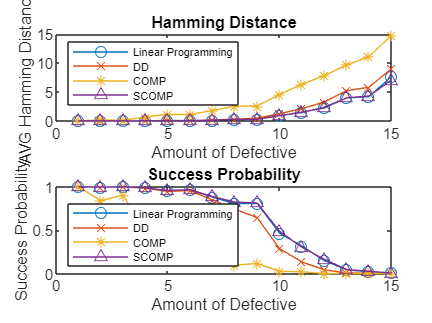


% Creation of the Figure.
figure;

% Plot the first subplot
subplot(2, 1, 1);
plot(xMeasurment, yplot_lin_prog,"o-");
hold on;
plot(xMeasurment, yplot,"x-");
plot(xMeasurment, yplot_COMP,"*-");
plot(xMeasurment, yplot_SCOMP,"^-");
xlabel("Amount of Defective");
ylabel("AVG Hamming Distance");
ylim([0,15]);
title('Hamming Distance');

hLegend = legend('Linear Programming', 'DD', 'COMP', 'SCOMP', 'Location', 'northwest');
set(hLegend, 'FontSize', 6); % Adjust the font size of the legend

% Plot the second subplot
subplot(2, 1, 2);
plot(xMeasurment, ySplot_lin_prog,"o-");
hold on;
plot(xMeasurment, ySplot,"x-");
plot(xMeasurment, ySplot_COMP,"*-");
plot(xMeasurment, ySplot_SCOMP,"^-");
xlabel("Amount of Defective");
ylabel("Success Probability");
ylim([0,1]);
title('Success Probability');

% Create a common legend for both subplots
hLegend = legend('Linear Programming', 'DD', 'COMP', 'SCOMP', 'Location', 'southwest');
set(hLegend, 'FontSize', 6); % Adjust the font size of the legend





%saveas(gcf, 'Sparsity.png', 'png');